%load in the Data2

WaterGrabData = load('R,cfa8_20190830_150205,thresholded,DLC3_nClus19.mat');

%Add paths

addpath('waterGrab\playgrounds\hank');
addpath('labcommon\neuropreproc');
addpath('labcommon\util\matt\general');
addpath('labcommon\util\matt\plotting');
addpath('waterGrab\clustering');
addpath("waterGrab\clustering\examples\")
addpath('waterGrab\display');
addpath('waterGrab\preproc');
addpath('waterGrab\clustering\utils');
addpath("waterGrab\clustering\Community_BGLL_Matlab\")
addpath("waterGrab\clustering\evaluation\")
addpath('waterGrab\clustering\spectral\')

%Extract Water Grab Data Structs

Mstruct = WaterGrabData.M;
Rstruct = WaterGrabData.R;

%Clustering Reaches

tPts = -20:10:480;
% Annotate the R struct with further event information
R = waterGrabAnnotateBehavHank(Rstruct, 2);
% Choose the event to lock the behavioral data to, Lift gives cleanest rotations so far
eventName = 'liftTime';
% This generates a data struct with the 3D locked kinematic data for all markers
data = eventLockCams3Hank(R, eventName, tPts);

%% Config to screen
% Call the configuration function for waterGrab analyses
config = configureWG;

%% Screen data
% Change the flag to screen the data
config.screenParams = 1;
% Set the skeletonized markers to screen with
config.skeleton = [[1,5]; [2,5]; [3,6]; [4, 6]; [5,6]; [5,7]; [6,7]];
% Screen the locked trials based on skeleton link lengths, 1.6 is a good threshold to use for the median distance, 
% Increasing the final argument will include more trials, decreasing it will screen out more
[data, R] = screenReaches3D(data, R, config.skeleton, 1.6);

Found 334/417 good trials in (1.9) s
Good trials: 
Links:      Avg # Bad Distances:      
1 - 5       0.004931
2 - 5       0.002466
3 - 6       0.001350
4 - 6       0.002172
5 - 6       0.002290
5 - 7       0.017083
6 - 7       0.016731



%% Config to cluster
% These are the four finger markers and two reliable paw markers for the Right Fore Paw (RFP)
config.markers2Clus = 1:6;
% Change this parameter to change the # of clusters, lower k = higher # clusters
config.k = 2;
% Parameter to cluster the kinematics based on a subselection of time points from the data struct
config.tPts2Clus = tPts;

%% Cluster data
% Main clustering script, uses Louvain clustering with an in-house distance metric
[data, R, M, clustCounts] = waterGrabCluster3D(data, R, Mstruct, config, 'l'); 

% This prints the number of clusters to the command line
fprintf('Pos nClus %i \n', length(clustCounts.Pos)); 

Pos nClus 19 



ClusterIds = [data(:).PosCluster];

%Setting up Dataset for Noise Correlation Analysis

DuringReach = waterGrabAnnotateBehav(Rstruct, 'R');
DuringReach = [DuringReach(:).nGrabs1000Water;DuringReach(:).nGrabs1000FirstGrab];
FirstDim = DuringReach(1, :) == 1;
SecondDim = DuringReach(2, :) == 1;
[~, DuringReachTrials] = find(FirstDim==1 & SecondDim==1);



Times = {0:10:350, -200:10:400, 500:10:1500};
Events = {'bothRestT', 'grabTime'};

for i=1:length(Times)
    
    if i == 1
    Time = Times{i};
    PreMove = eventLockData(Rstruct, Mstruct, ...
        Events{i}, Time);
    Empty = [PreMove(:).locked];
    PreMove = PreMove(~cellfun(@isempty,{PreMove.data}));
    LRPreMove = [Rstruct(:).LR];
    LRPreMove(Empty == 0) = [];
    
    RoiNums = size(PreMove(1).data, 2);
    
    
    elseif i == 2
        
        Time = Times{i};
        DurMove = eventLockData(Rstruct, Mstruct, ...
        Events{i}, Time);
        
        DuringGrab = struct;
        
        for j=1:length(DuringReachTrials)
        DuringGrab(j).data = DurMove(DuringReachTrials(j)).data; 
        DuringGrab(j).locked = DurMove(DuringReachTrials(j)).locked;
    
        end 
        
        LRDurMove = [Rstruct(:).LR];
        LRDurMove = LRDurMove(DuringReachTrials);
        
    elseif i == 3
        
        Time = Times{i};
        Event = Events{i-1};
        
        PostMove = eventLockData(Rstruct, Mstruct, ...
            Event, Time);
        
        Empty = [PostMove(:).locked];
        PostMove = PostMove(~cellfun(@isempty,{PostMove.data}));
        LRPostMove = [Rstruct(:).LR];
        LRPostMove(Empty == 0) = [];
        
    end
end


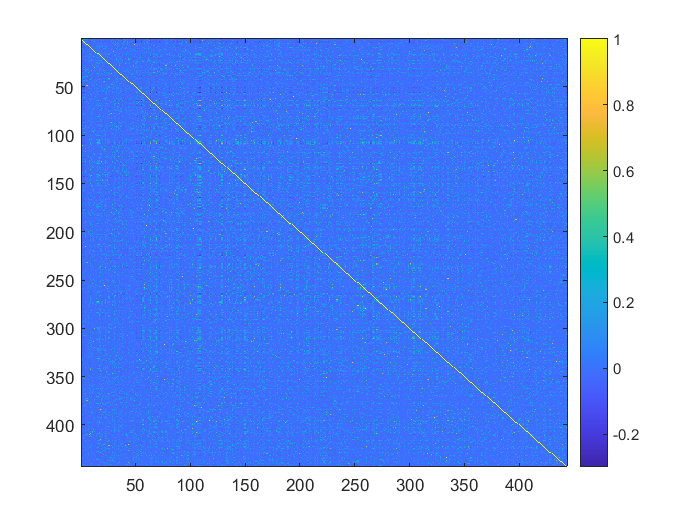

%NeuralData Noise, NoiseResp, left, right and overall Computation
%Input data matrix, timeline and NumRoi

[NoiseCorr, NoisePreMove, SigRois] = NeuralDataNoiseCorr(PreMove, Times{1},...
    RoiNums, LRPreMove, 0);

imagesc(NoiseCorr)
colorbar

mean(NoiseCorr, 'all')

ans = 0.0139

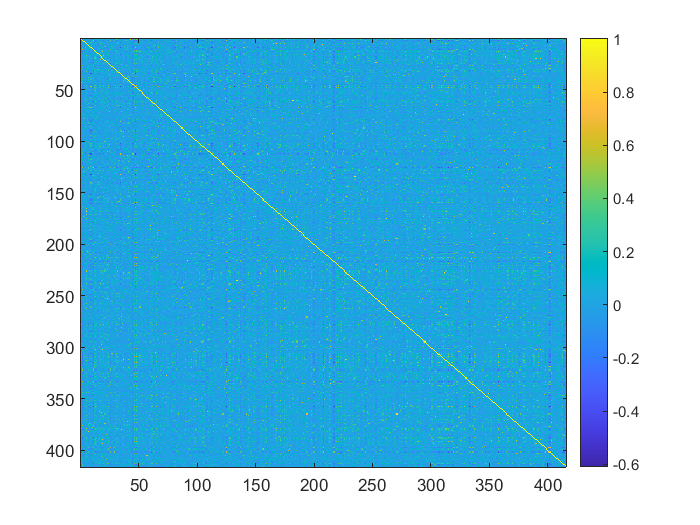

[NoiseCorr, NoiseDurMove, SigRois] = NeuralDataNoiseCorr(DuringGrab, Times{2},...
    RoiNums, LRDurMove, 0);

imagesc(NoiseCorr)
colorbar

mean(NoiseCorr, 'all')

ans = 0.0226

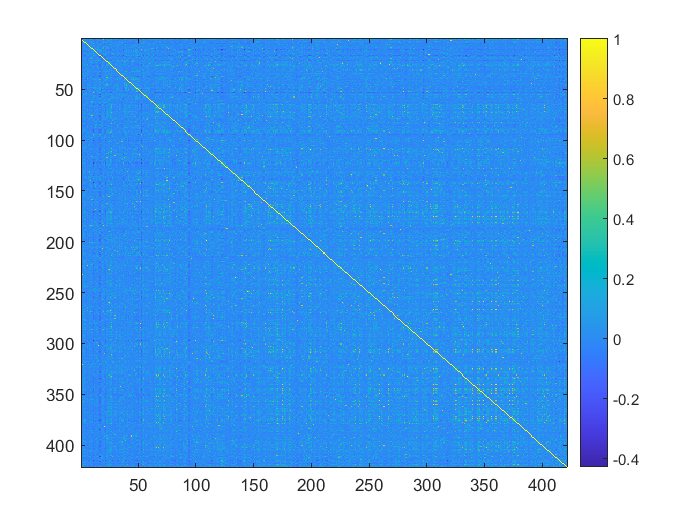

[NoiseCorr, NoisePostMove, SigRois] = NeuralDataNoiseCorr(PostMove, Times{3},...
    RoiNums, LRPostMove, 0);

imagesc(NoiseCorr)
colorbar

mean(NoiseCorr, 'all')

ans = 0.0266

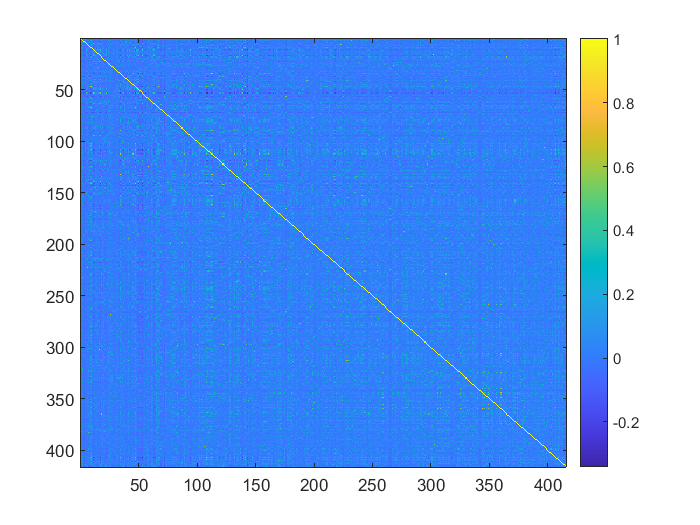

% Combining different noise response matrices into to compute a piecewise
% noise correlation matrix. 

PieceWiseMat = [NoisePreMove(:, 1:416);NoiseDurMove(:, 1:end);NoisePostMove(:, 1:416)];


test = corrcoef(PieceWiseMat);

imagesc(test)
colorbar



mean(test, 'all')

ans = 0.0226

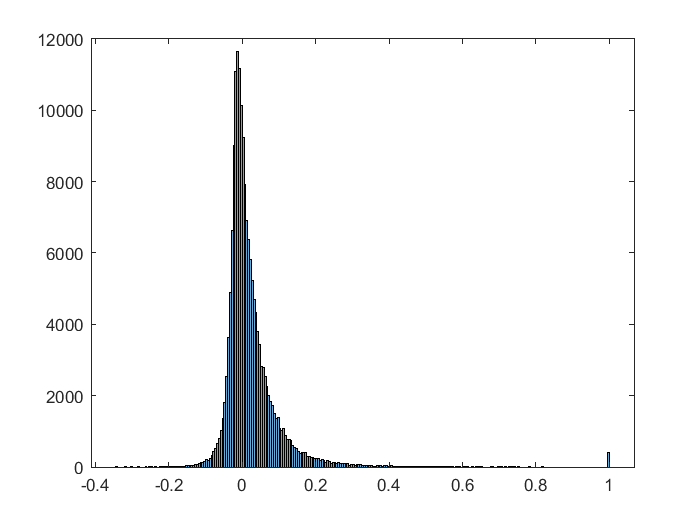


histogram(test)

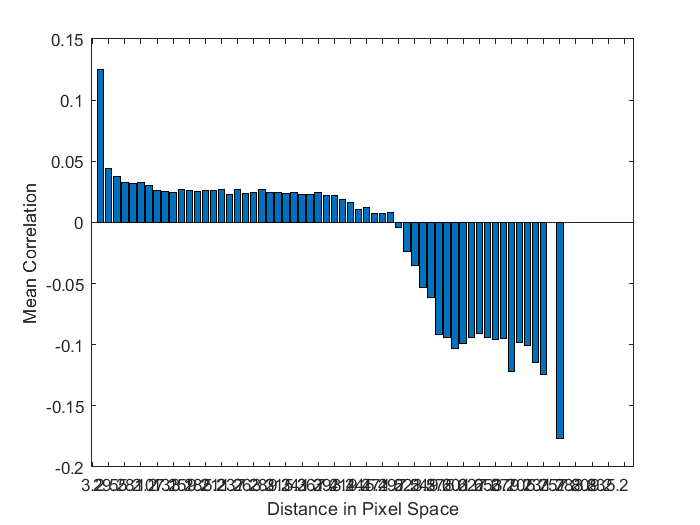

[MeanCorrDist, Edges, RoiDist, Allocate] = NeuroDistCorr(NoiseCorr, Mstruct.ROICentroidsYX, SigRois, 13);

bar(MeanCorrDist)
set(gca, 'XTick', 0:2:max(Edges,[], 'all'))
xticklabels(round(Edges(1:2:end), 1))
ylabel("Mean Correlation")
xlabel("Distance in Pixel Space")

%Try Spectral Clustering
cmap = parula(2);
Clusters = dmapSpectral((1-NoiseCorr), 2, 10);
ClusterMat = Clusters .* Clusters';

Cluster1 = ClusterMat == 1;
Cluster2 = ClusterMat == 4;

%Mean of Cluster 1
Cluster1NC = zeros(421, 421);
Cluster1NC(Cluster1) = NoiseCorr(Cluster1);

MeanClust1NC = sum(Cluster1NC, 'all')/length(NoiseCorr(Cluster1NC ~= 0));

%Mean Cluster 2
Cluster2NC = zeros(421, 421);
Cluster2NC(Cluster2) = NoiseCorr(Cluster2);

MeanClust2NC = sum(Cluster2NC, 'all')/length(NoiseCorr(Cluster2NC ~= 0));

%ROIs to be punished Cluster 1
Cluster1Dist = zeros(421, 421);
Cluster1Dist(Cluster1) = RoiDist(Cluster1);

MeanDistClust1 = nansum(Cluster1Dist, 'all')/ length(RoiDist(Cluster1Dist ~= 0));
StdDistClust1 = nanstd(reshape(Cluster1Dist, 1, []));
PunishClust1 = Cluster1Dist >= (MeanDistClust1 +1.5*StdDistClust1);

%ROIs to be punished Cluster 2
Cluster2Dist = zeros(421, 421);
Cluster2Dist(Cluster2) = RoiDist(Cluster2);

MeanDistClust2 = nansum(Cluster2Dist, 'all')/ length(RoiDist(Cluster2Dist ~= 0));
StdDistClust2 = nanstd(reshape(Cluster2Dist, 1, []));
PunishClust2 = Cluster2Dist >= (MeanDistClust2 + 1.5*StdDistClust2);


NoiseCorr(PunishClust2) = NoiseCorr(PunishClust2) - MeanClust2NC;
NoiseCorr(PunishClust1) = NoiseCorr(PunishClust1) - MeanClust1NC;

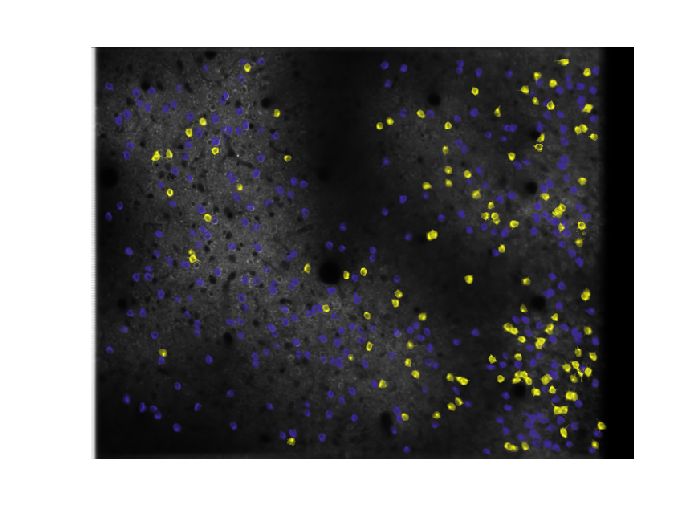

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 31
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties



Cmap = zeros(length(Clusters), 3);
for i=1:length(unique(Clusters))
    
    Cluster = Clusters == i;
    
    Cmap(Cluster, :) = repelem(cmap(i, :)', 1, length(Cmap(Cluster)))';
    
    
end

showROIs(Mstruct,SigRois, 'colors', Cmap)

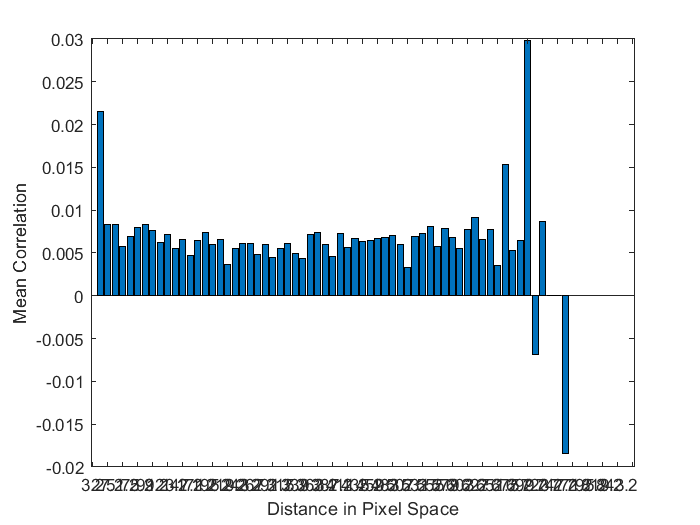

[MeanCorrDist, Edges,~, Allocate] = NeuroDistCorr(test2, Mstruct.ROICentroidsYX, SigRois, 12);

bar(MeanCorrDist)
set(gca, 'XTick', 0:2:max(Edges,[], 'all'))
xticklabels(round(Edges(1:2:end), 1))
ylabel("Mean Correlation")
xlabel("Distance in Pixel Space")

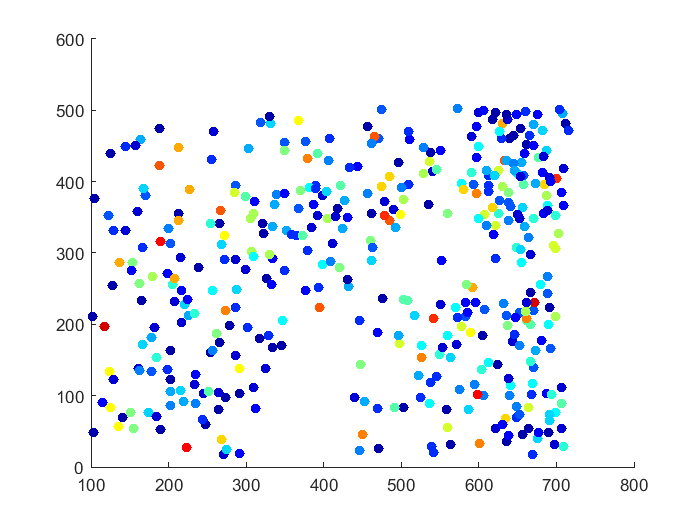

dists = [Mstruct.ROICentroidsYX];
cmap = jet(length(unique(C)));
figure
for i=1:length(SigRois)
    
    scatter(dists(SigRois(i), 2), dists(SigRois(i), 1), [], cmap(C(i, 1), :),...
        "filled", "LineWidth", 2)
    hold on  
end
hold off

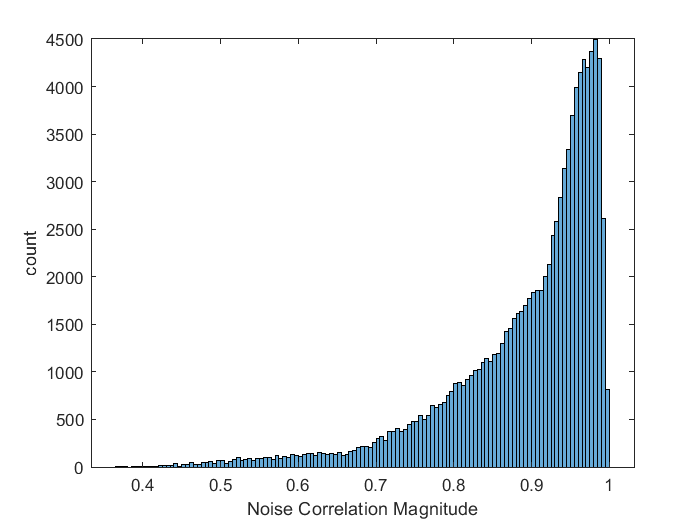




histogram(NoiseCorr)
xlabel("Noise Correlation Magnitude")
ylabel("count")

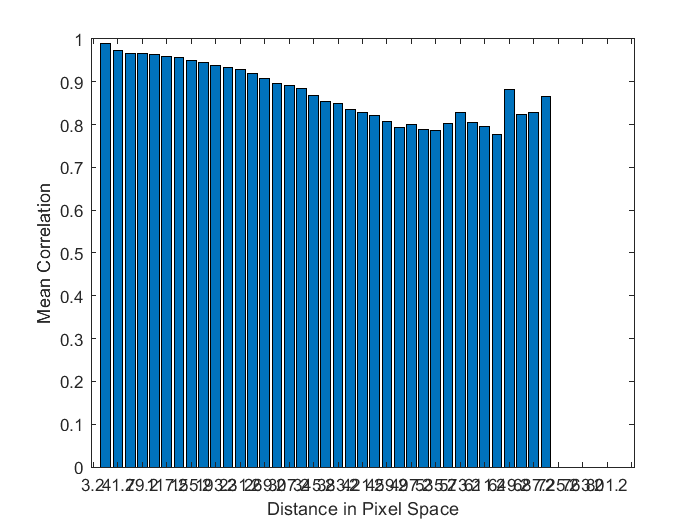

%Noise Correlation as a function of distance between ROIs
[MeanCorrDist, Edges,~] = NeuroDistCorr(NoiseCorr, Mstruct.ROICentroidsYX, SigRois, 19);

bar(MeanCorrDist)
set(gca, 'XTick', 0:2:max(Edges,[], 'all'))
xticklabels(round(Edges(1:2:end), 1))
ylabel("Mean Correlation")
xlabel("Distance in Pixel Space")